"Convolution" for Multiplication

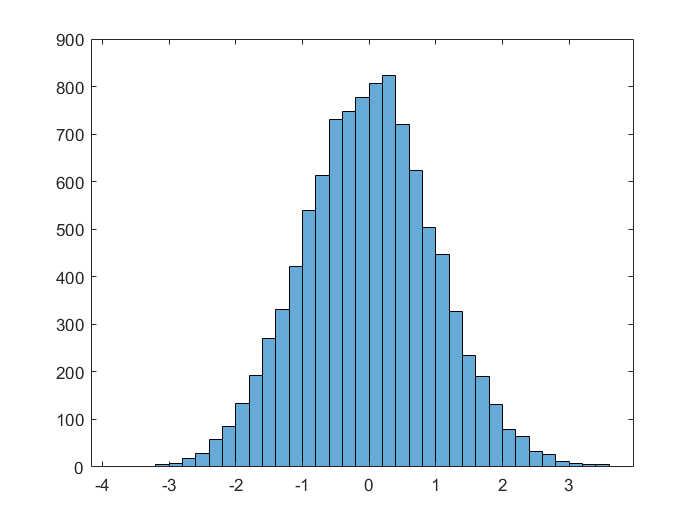

N = 10000;
standard_norm_vars1 = randn(1,N);
histogram(standard_norm_vars1)

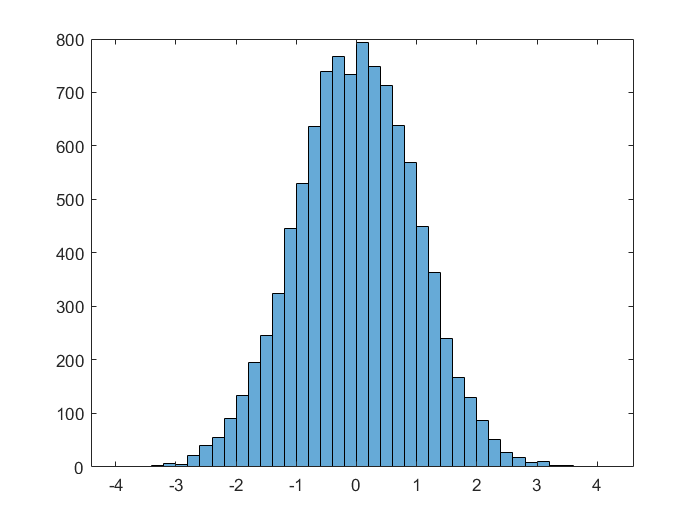

standard_norm_vars2 = randn(1,N);
histogram(standard_norm_vars2)

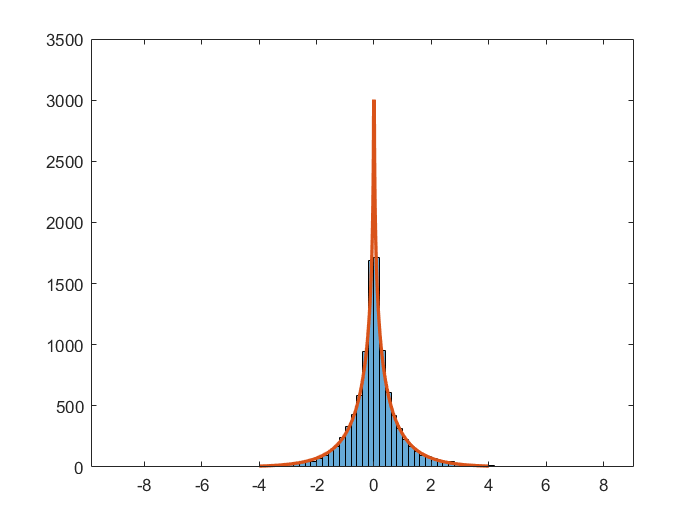


norm_var_products = standard_norm_vars1.*standard_norm_vars2;


h = histogram(norm_var_products);
hold on
plot(-4:.01:4,N*h.BinWidth*besselk(0,abs(-4:.01:4))/pi,'LineWidth',2)
hold off

% Normalization Check
% integral(@(x) besselk(0,abs(x))/pi,-10,10)


A Theory About DSGs

center1 = 1/2;
center2 = 6/10;
spread1 = 1/20;
spread2 = 1/15;

DSG_vars1 = double_stunted_gaussian_inverse_gamma(rand(1,N),center1,spread1);

'double_stunted_gaussian_inverse_gamma' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\wynga\OneDrive\Desktop\PhD_Research\Functions\Inverse Gammas

Change the MATLAB current folder or add its folder to the MATLAB path.

histogram(DSG_vars1)
DSG_vars2 = double_stunted_gaussian_inverse_gamma(rand(1,N),center2,spread2);
histogram(DSG_vars2)

DSG_products = DSG_vars1.*DSG_vars2;
h = histogram(DSG_products);
hold on

estimated_function = @(x) (1/spread1*spread2)*(besselk(0,abs(x))/pi + (center1+center2)*normpdf(x) + center1*center2);
% Normalization Check
A = 1/integral(@(x) estimated_function(x)/pi,-10,10);
estimated_function = @(x) A*estimated_function(x);
integral(@(x) estimated_function(x)/pi,-10,10)

plot(0:.001:1,N*h.BinWidth*estimated_function(0:.001:1),'LineWidth',2)
hold off

plot(0:.001:1,N*h.BinWidth*estimated_function(0:.001:1),'LineWidth',2)